### **Método de Newton-Raphson**** (Tangentes)**


$$x^{k+1} = x^{k}-\frac{f(x^{k})}{f'(x^{k})}$$


Vamos encontrar o zero da função $f(x) = -0.5x^{2}+2.5x+4.5$ no intervalo de $[-2.5,0]$utilizando o método de Newton-Raphson, com  chute inicial $x^{0} = -1$ e erro relativo igual ou menor que $10^{-4}$.

**Graficamente, **

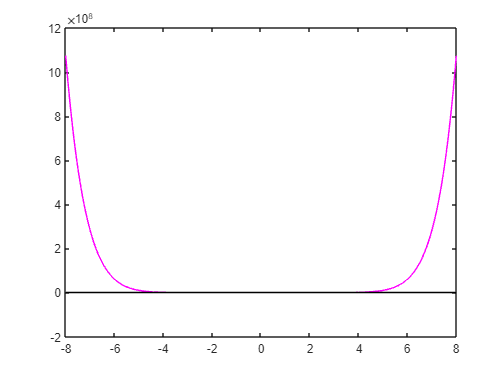

x= -8:0.01:8;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off

**Implementação do MPF:**

format long
x0 = 0.2;
tol = 10^-4;
k = 0;
erro_relativo = 10;

while erro_relativo > tol
    k = k + 1;
    x = x0 - fun(x0)./gfun(x0);
    xk(k, :) = x0;
    fk(k, :) = fun(x0);
    erro_relativo = abs(x - x0)/abs(x);
    x0 = x;
end
[xk, fk]

ans = 1.0e+52 *

   0.000000000000000  -0.000000000000000
   0.000000000000000   8.078010116026997
   0.000000000000000   2.816627966368314
   0.000000000000000   0.982097445655340
   0.000000000000000   0.342436205377298
   0.000000000000000   0.119400121924720
   0.000000000000000   0.041632248260461
   0.000000000000000   0.014516267381314
   0.000000000000000   0.005061509466591
   0.000000000000000   0.001764839225362


fprintf("O valor da aproximação para X é %d -> O número de iterações é %d", x, k)

O valor da aproximação para X é 1.000000e+00 -> O número de iterações é 120

**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = x.^10 -1;
end
function g1 = gfun(x)
    g1 = 10*x.^9;
end
